# A Poisson problem with an unbounded edge

Set up a quantum graph in the form of a dumbbell plus one extra unbounded edge

Solve the vertex-value problem 


$$\triangle u = f \\
\sum u'(\mathtt{v_1})+ u(\mathtt{v_1}) = 1 \\
\sum u'(\mathtt{v_2})+ u(\mathtt{v_2}) = \frac{-31}{9}\\
\lim_{x\to\infty} u_3(x) = 0
$$


where 

- The functions on the right-hand-sides are $f = \left\{\cos{x}, x, \sin{2x}, \sech{x} \right\}$on the four edges.

- the edges have lengths $\left\{
2\pi, 4, 2\pi, 1
\right\}$.

- The exact solutions on the edges are $\left\{
\frac{50}{9}-\cos (x)
,
\frac{1}{18} \left(3 x^3-64 x+82\right)
,
1-\frac{1}{4} \sin (2 x)
,
\text{sech}(x)
\right\}$.

The exact solution is computed in the accompanying Mathematica notebook of the same name.

## Quantum graph definition

s=[1 1 2 2];
t=[1 2 2 3];
L=[2*pi 4 2*pi inf];
robinCoeff=[1 1 nan];

## The exact solution

u1=@(x)(50/9-cos(x));
u2=@(x)(82 -64*x +3*x.^3)/18;
u3=@(x)(1-sin(2*x)/4);
u4=@(x)sech(x);

## The right hand sides

Edges and nodes

f1=@(x)cos(x);
f2=@(x)x;
f3=@(x)sin(2*x);
f4=@(x)sech(x).*(1-2*sech(x).^2);
nodeData = [1;-31/9;0];

## Solve the system twice,

doubling the number of discretization points between the two runs.

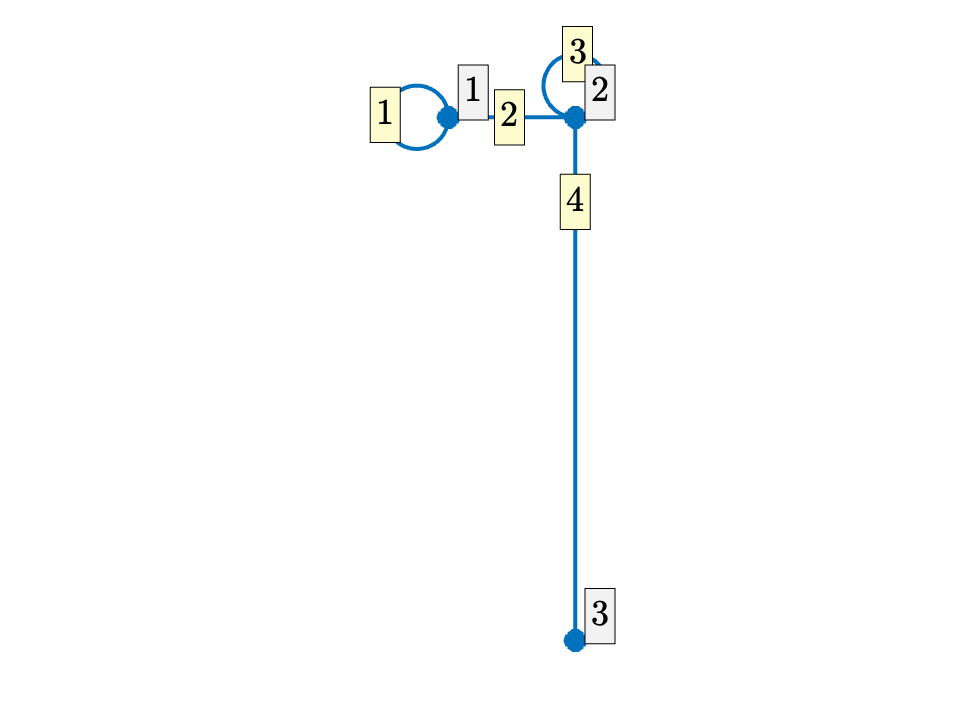

nx = [10 20];
errors=zeros(1,2);
for k=1:2

Define the quantum graph (all that changes between the two iterates is the number of discretization points per unit length).

    Phi=quantumGraph(s,t,L,'RobinCoeff',robinCoeff,'nxVec',nx(k));
    Phi.addPlotCoords(@poissonExamplePlotCoords);
    Phi.plot('layout')

Set up the exact solution on the edges

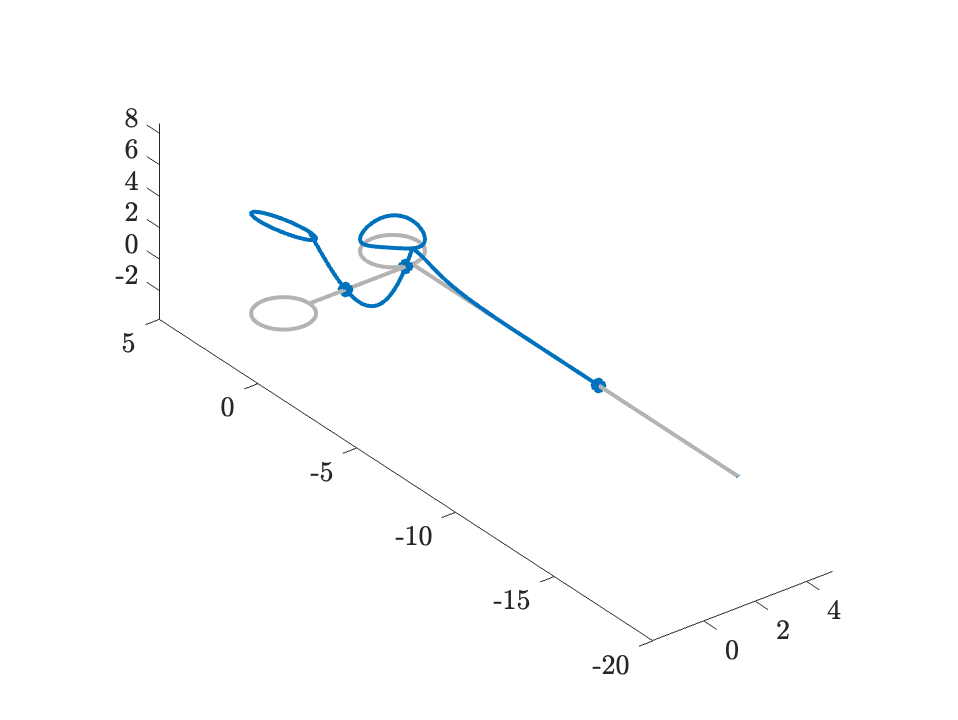

    exactSolution = Phi.applyFunctionsToAllEdges({u1,u2,u3,u4});

Set up the nonhomogeneous data on the edges

    edgeData = Phi.applyFunctionsToAllEdges({f1,f2,f3,f4});

The error with N=16 is 9.4616e-03.


Solve and compute errors

    numericalSolution = Phi.solvePoisson('edgeData',edgeData,'nodeData',nodeData);

The error with N=32 is 2.3655e-03.


    errors(k)= Phi.norm(exactSolution-numericalSolution);

The maximum error went down by a factor of 3.9998.


end

Plot the solution

Phi.plot(numericalSolution)

Display the reduction in error. Since the discretization is second order, this should be about a factor of four.

fprintf('The error with N=16 is %0.4d.\n',errors(1))
fprintf('The error with N=32 is %0.4d.\n',errors(2))
fprintf("The maximum error went down by a factor of %0.4f.\n", errors(1)/errors(2) )